# Analysis of the connection of two pipes

close all;
clear all;
clc;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_3_pipes_r_250um');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_3_pipes_r_250um


#### Parameters

%call to the parameters file
Parameters

p0 = 7

mu = 9.9792e-04

D_coeff = 5.3000e-09

#### Flow rate for a given pressure drop  

**Description:** This block assumes a syringe is connected to the inlet of the pipe and introduces a constant flow rate Q. The pressure formula follows the Hagen–Poiseuille equation [1, Eq. (3.1)  pp. 43 and Table 3.1 pp.47]

$\Delta P=\frac{8\mu L Q}{\pi r^4}$, (1)

where 

$\mu$ is the water viscosity,

$L$ is the channel length,

$r$ is the radius of the pipe.

% Q_nL_per_min=10;
% Q=Q_nL_per_min*10^(-9)*10^(-3)/60;
% Delta_P=(8*mu_Water*L_outer)/(pi*radius_cylinder_1^4)*Q
% Delta_P_mmHg=Delta_P/133.322
%flow rate in [m^3/s]
Q_m3_s=p0*(pi*r_vec.^4)/(8*mu*l_vec(end));
%flow rate in [uL/min]
Q_uL_m=Q_m3_s*60/(1e-6*1e-3);
disp(['Min Q_ul_m=',num2str(min(Q_uL_m))])

Min Q_ul_m=2.1179


disp(['Max Q_ul_m=',num2str(max(Q_uL_m))])

Max Q_ul_m=4.7262



%flow rate in [uL/h]
Q_uL_h=Q_m3_s*60*60/(1e-6*1e-3);


#### Péclet condition

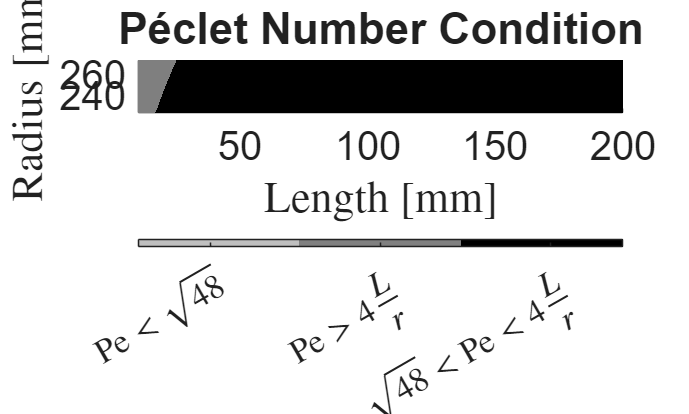

Pe_cond=zeros(length(r_vec),length(l_vec));

for i_r=1:length(r_vec)

    %i_r/length(r_vec)*100

    for i_l=1:length(l_vec)

        %Evaluating the mean velocity [2, pag. 54]
        v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l));

        %Evaluating the Effective Diffusion
        %[1, Eq.(4.54) pp.77]
        D_eff=r_vec(i_r)^2*v_char^2/48/D_coeff;

        %Validating the diffusion within the pipe
        %Evaluation of the Péclet number, this evaluation follows [1,Eq. (4.44) pp.75]
        Pe=r_vec(i_r)*v_char/D_coeff;
        
        %Diffusion occurred along the radial axis and x-axis
        if(Pe<4*l_vec(i_l)/r_vec(i_r) && Pe>sqrt(48))
            Pe_cond(i_r,i_l)=1;

        %Diffusion hasn't occurred along the radial axis and x-axis
        elseif(Pe>4*l_vec(i_l)/r_vec(i_r))
            Pe_cond(i_r,i_l)=0;
        
        %Diffusion hasn't occurred along the axis
        elseif (Pe<sqrt(48))
            Pe_cond(i_r,i_l)=-1;
        end
    end
end


% Plotting the Pe_cond matrix

figure;

% Plot for all conditions in a single plot
hold on;
imagesc(l_vec*1e3, r_vec*1e6, Pe_cond);
% colormap([0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.0072 0.4470 0.7410]); % Colors for 0, -1, and 1
colormap([0.75, 0.75, 0.75; 0.5, 0.5, 0.5; 0, 0, 0]); % Colors for 0, -1, and 1
caxis([-1 1]); % Set color axis limits to match Pe_cond values

text(150,1.5,{'Validation', 'zone'},'FontSize',fontsize,'Color','w','HorizontalAlignment','center');

% Adjust the transparency for better visualization

% Create a colorbar and set its ticks and labels
cb = colorbar('Ticks', [-0.7, 0, 0.7], 'TickLabels', {'$\mathrm{Pe}<\sqrt{48}$', '$\mathrm{Pe}>4\frac{L}{r}$', '$\sqrt{48}<\mathrm{Pe}<4\frac{L}{r}$'}, 'TickLabelInterpreter', 'latex', 'FontSize', fontsize-3,'Location','southoutside');
% cb.Layout.Tile='south';

% Set the color of the colorbar with transparency
%set(colorbarHandle, 'alpha', 0.5); % RGBA format, where A is the alpha value
%alpha(0.5);

xlabel('Length [mm]','Interpreter','latex');
ylabel('Radius [mm]','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(end)*1e3 r_vec(1)*1e6 r_vec(end)*1e6])
set(gca, 'YDir', 'normal');
title('Péclet Number Condition');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;

#### Peak time and peak amplitude vs radius and length

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'tau_vs_r_l.mat'))


#### Synthesis of length and radius for a given tau_sample

% Given value of tau
tau_value = tau_sample; % Replace 'tau' with the actual value if needed

% Finding the closest coordinates to tau, 2*tau, and 3*tau in the peak_tau matrix
tau_coords = zeros(3, 4); % Preallocate for coordinates

for k = 1:3
    target_value = k * tau_value;
    [row, col] = find(abs(peak_tau - target_value) == min(min(abs(peak_tau - target_value))));
    tau_coords(k, :) = [row, col, target_value, peak_amp(row,col)];
end

%find the coordinates where calculations are zero
[row, col] = find(peak_tau < peak_tau(end,1),1);
disp('Row coordinates where peak_tau is zero:');

Row coordinates where peak_tau is zero:


disp(row);

     1



disp('Column coordinates where peak_tau is zero:');

Column coordinates where peak_tau is zero:


disp(col);

    69



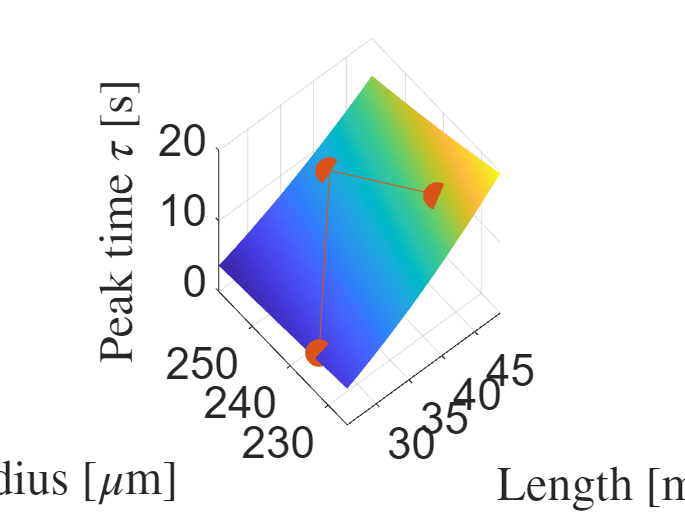

col=col-1;

if isempty(col)
    [~,col]=size(peak_tau);
end

% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec(1:col)*1e3, r_vec(1:col)*1e6, peak_tau(1:col,1:col));
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Radius [$\mu$m]','Interpreter','latex');
zlabel('Peak time $\tau$ [s]','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(col)*1e3 r_vec(1)*1e6 r_vec(col)*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold on; % Keep the current plot

% Superposing the tau_coords on the plot
plot3(l_vec(tau_coords(:,2))*1e3, r_vec(tau_coords(:,1))*1e6, tau_coords(:,3), 'o-',...
    'MarkerSize', 12, 'Color','#D95319','MarkerFaceColor','#D95319');

hold off;
view(-40, 51); % Adjust the view angle for better visualization

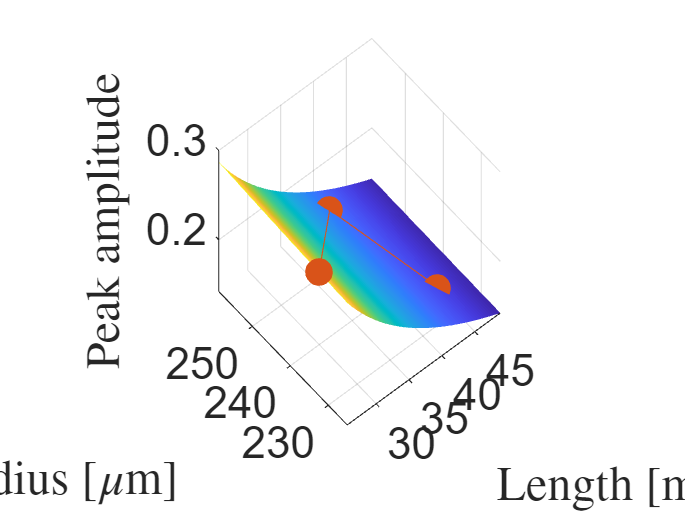


% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec(1:col)*1e3, r_vec(1:col)*1e6, peak_amp(1:col,1:col));
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Radius [$\mu$m]','Interpreter','latex');
zlabel('Peak amplitude','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(col)*1e3 r_vec(1)*1e6 r_vec(col)*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold on;
view(-40, 51); % Adjust the view angle for better visualization

% Superposing the tau_coords on the plot
plot3(l_vec(tau_coords(:,2))*1e3, r_vec(tau_coords(:,1))*1e6, tau_coords(:,4), '-o',...
    'MarkerSize', 12, 'Color','#D95319','MarkerFaceColor','#D95319');
hold off;

#### Gradient analysis for the peak of the CNN pipes

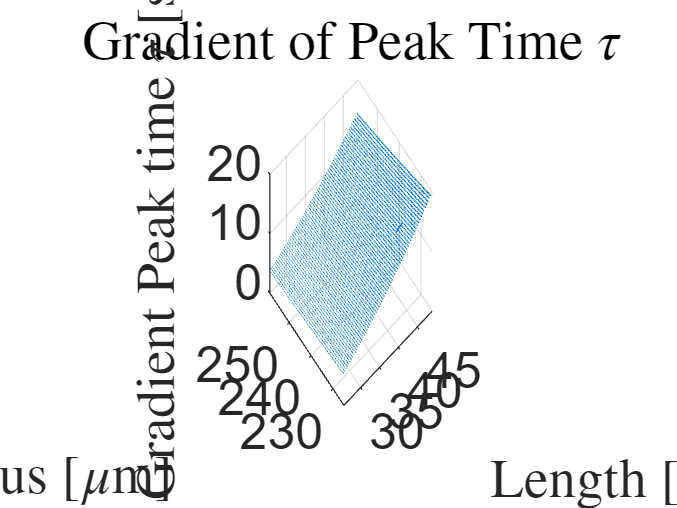

% Evaluating the gradient of the peak_tau matrix
[gradient_tau_x, gradient_tau_y] = gradient(peak_tau);

dL=l_vec(2)-l_vec(1);
dr=r_vec(2)-r_vec(1);

% Plotting the gradient of the peak_tau matrix
figure;
quiver3(l_vec(1:col)*1e3, r_vec(1:col)*1e6, peak_tau(1:col, 1:col),...
    gradient_tau_x(1:col, 1:col), gradient_tau_y(1:col, 1:col),...
    zeros(size(gradient_tau_x(1:col, 1:col))), 'AutoScale', 'off');
xlabel('Length [mm]','Interpreter','latex');
ylabel('Radius [$\mu$m]','Interpreter','latex');
zlabel('Gradient Peak time $\tau$ [s]','Interpreter','latex');
title('Gradient of Peak Time $\tau$','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(col)*1e3 r_vec(1)*1e6 r_vec(col)*1e6]);
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
view(-40, 51); % Adjust the view angle for better visualization

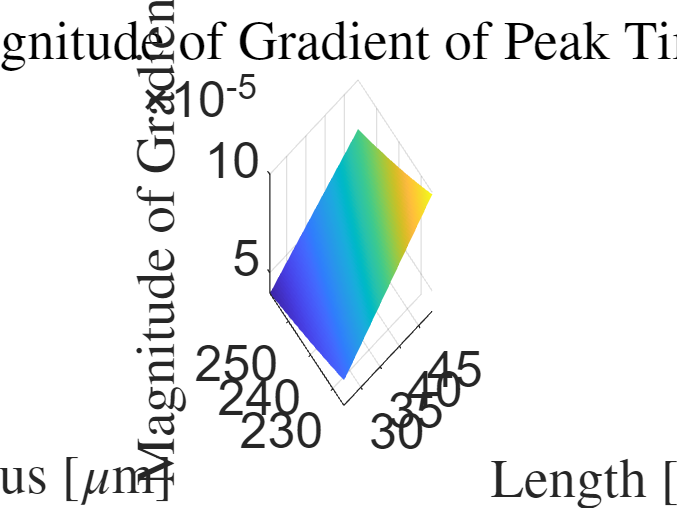


% Calculating the magnitude of the gradient
gradient_magnitude = sqrt((gradient_tau_x*dL).^2 + (gradient_tau_y*dr).^2);

% Plotting the magnitude of the gradient
figure;
s=surf(l_vec(1:col-1)*1e3, r_vec(1:col-1)*1e6, gradient_magnitude(1:col-1, 1:col-1));
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Radius [$\mu$m]','Interpreter','latex');
zlabel('Magnitude of Gradient','Interpreter','latex');
title('Magnitude of Gradient of Peak Time $\tau$','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(col-1)*1e3 r_vec(1)*1e6 r_vec(col-1)*1e6]);
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
view(-40, 51); % Adjust the view angle for better visualization

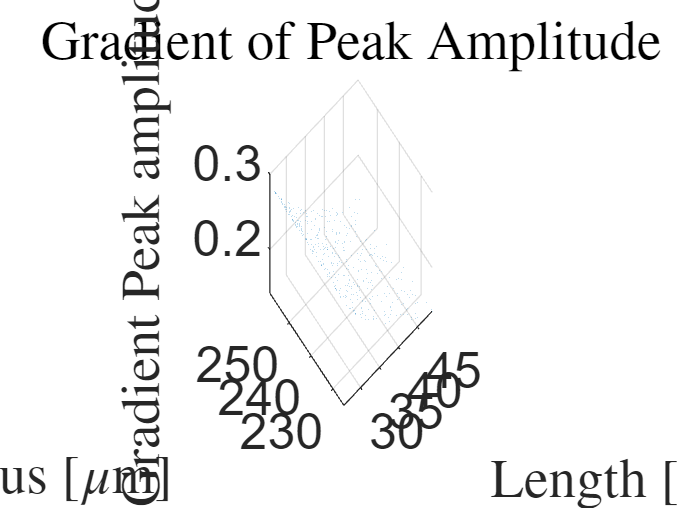


% Evaluating the gradient of the peak_tau matrix
[gradient_amp_x, gradient_amp_y] = gradient(peak_tau);

% Evaluating the gradient of the peak_amp matrix
[gradient_amp_x, gradient_amp_y] = gradient(peak_amp);

% Plotting the gradient of the peak_amp matrix
figure;
quiver3(l_vec(1:col)*1e3, r_vec(1:col)*1e6, peak_amp(1:col, 1:col), gradient_amp_x(1:col, 1:col), gradient_amp_y(1:col, 1:col), zeros(size(gradient_amp_x(1:col, 1:col))), 'AutoScale', 'off');
xlabel('Length [mm]','Interpreter','latex');
ylabel('Radius [$\mu$m]','Interpreter','latex');
zlabel('Gradient Peak amplitude','Interpreter','latex');
title('Gradient of Peak Amplitude','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(col)*1e3 r_vec(1)*1e6 r_vec(col)*1e6]);
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
view(-40, 51); % Adjust the view angle for better visualization

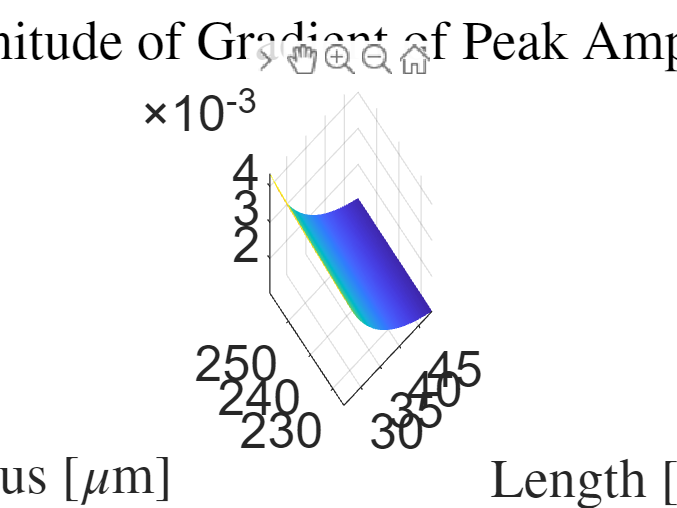


% Calculating the magnitude of the gradient for peak_amp
gradient_amp_magnitude = sqrt(gradient_amp_x.^2 + gradient_amp_y.^2);

% Plotting the magnitude of the gradient for peak_amp
figure;
s=surf(l_vec(1:col-1)*1e3, r_vec(1:col-1)*1e6, gradient_amp_magnitude(1:col-1, 1:col-1));
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Radius [$\mu$m]','Interpreter','latex');
% zlabel('Magnitude of Gradient of Peak Amplitude','Interpreter','latex');
title('Magnitude of Gradient of Peak Amplitude','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(col-1)*1e3 r_vec(1)*1e6 r_vec(col-1)*1e6]);
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
view(-40, 51); % Adjust the view angle for better visualization

### Results for Pipe 1

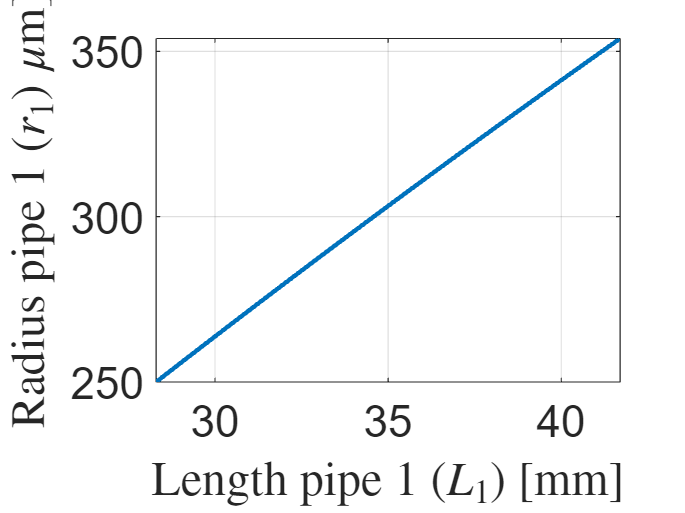

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'pipe_1_r_vs_l.mat'))

idx=find(r_vs_l_pipe_1~=0);
figure;
plot(l_vec(idx)*1e3,r_vs_l_pipe_1(idx)*1e6,'LineWidth',2); grid on;
xlabel('Length pipe 1 ($L_1$) [mm]','Interpreter','latex');
ylabel ('Radius pipe 1 ($r_1$) $\mu$m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

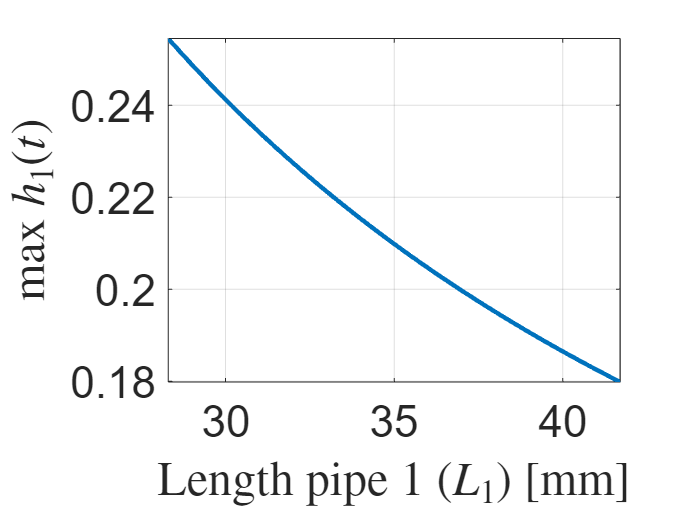


syms t
%Validation of time and peak amplitude sampling
peak_amp_pipe_1=zeros(1,length(idx));

% figure;

for i=1:length(idx)
    L_1=l_vec(idx(i));
    r_1=r_vs_l_pipe_1(idx(i));
    %Evaluating the mean velocity [2, pag. 54]
    v_char=r_1^2*p0/(3*mu*L_1);

    %Evaluating the Effective Diffusion
    %[1, Eq.(4.54) pp.77]
    D_eff=r_1^2*v_char^2/48/D_coeff;

    %Evaluating the concentration of the straigth channel
    c=1./2.*erfc((L_1-v_char*t)./(2*sqrt(D_eff*t)));
    %Evaluating the channel impulse response
    h=diff(c,t);
    % %for validation purposes only
    % fplot(h,[tau_1/10 3*tau_1]); grid on; hold on;

    %
    peak_amp_pipe_1(i)=subs(h,t,tau_1);
end

% %for validation purposes only
% xlabel('Time [s]','Interpreter','latex');
% ylabel ('Straigth pipe 1 $h_1(t)$','Interpreter','latex');
% set(gca,'FontSize',fontsize);

figure;
%% colecting the amplitude
plot(l_vec(idx)*1e3,peak_amp_pipe_1,'LineWidth',2);grid on;
xlabel('Length pipe 1 ($L_1$) [mm]','Interpreter','latex');
ylabel ('max $h_1(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);


%save the solutions for the pipe 1
%Saving results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

L_1_vec=l_vec(idx);
r_1_vec=r_vs_l_pipe_1(idx);
save(fullfile(outputFolder, 'Pipe_1_sol.mat') ,'L_1_vec','r_1_vec','tau_1');

### Plotting $h_1(t)$

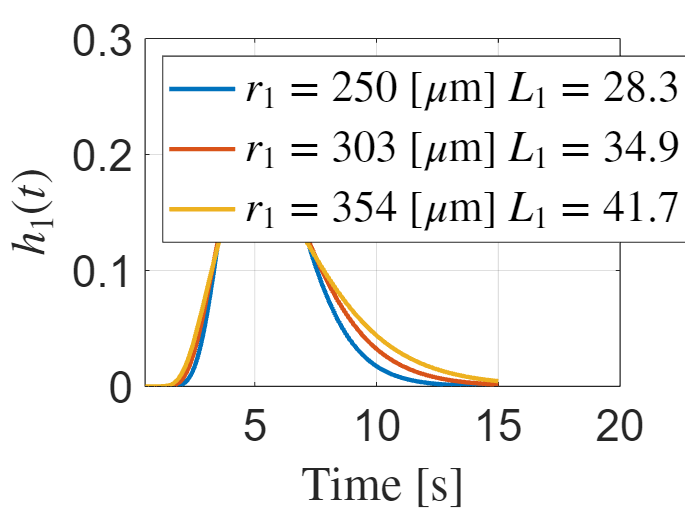

syms t

samples=[1,round(length(idx)/2),length(idx)];

figure;
legend_text=cell(1,length(samples));
m=1; %index for the legend

for i=samples;
    L_1=l_vec(idx(i));
    r_1=r_vs_l_pipe_1(idx(i));
    %Evaluating the mean velocity [2, pag. 54]
    v_char=r_1^2*p0/(3*mu*L_1);

    %Evaluating the Effective Diffusion
    %[1, Eq.(4.54) pp.77]
    D_eff=r_1^2*v_char^2/48/D_coeff;

    %Evaluating the concentration of the straigth channel
    c=1./2.*erfc((L_1-v_char*t)./(2*sqrt(D_eff*t)));
    %Evaluating the channel impulse response
    h=diff(c,t);
    %for validation purposes only
    fplot(h,[tau_1/10 3*tau_1],'LineWidth',2); grid on; hold on;

    %legend on the plot
    legend_text{m}=strcat('$r_1=',num2str(r_1*1e6,3),'$ [$\mu$m] $L_1=',num2str(L_1*1e3,3),'$ [mm]');
    m=m+1;

end

legend({legend_text{:}},...
    'Location','northwest','NumColumns',1,'Interpreter',"latex",'FontSize',fontsize);%

axis([tau_1/10 4*tau_1 0 0.3])

%for validation purposes only
xlabel('Time [s]','Interpreter','latex');
ylabel ('$h_1(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);
hold off;

#### Evaluating the approximate time to fill in the reader

%Evaluating the reader volume and time to fill the volume
r_Reader=500e-6/2;
r_pipe=120e-6;%solution from the h1(t) plot
l_pipe=14.2e-3;%solution from the h1(t) plot
%flow rate in [m^3/s]
Q_m3_s=p0*(pi*r_pipe.^4)/(8*mu*l_pipe);
%flow rate in [uL/min]
Q_uL_m=Q_m3_s*60/(1e-6*1e-3)

Q_uL_m = 2.4135

reader_delay=2*pi*r_Reader^2*r_pipe/Q_m3_s

reader_delay = 1.1715



%Evaluating the CNN delay
v_char=r_pipe^2*p0/(3*mu*l_pipe);
%CNN_delay=l_pipe/v_char

reader_delay/4*100

ans = 29.2874

### Results Pipe 2

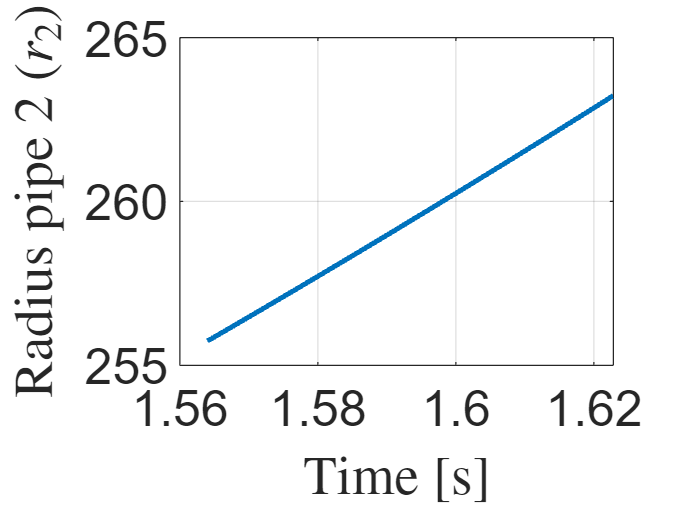

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'pipe_2_r_vs_varphi.mat'))

idx=find(r_vs_varphi_pipe_2~=0);

figure;
plot(varphi_vec(idx),r_vs_varphi_pipe_2(idx)*1e6,'LineWidth',2); grid on;
xlabel('Turning angle ($\varphi$) [rad]','Interpreter','latex');
ylabel ('Radius pipe 2 ($r_2$) [$\mu$m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

%Validation
%Evaluating the channel impulse response
%Matlab code to evaluate the integral
syms t x rd r rd v varphi D C_0
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(2*r)*int(integrand, rd, 0, 2*r));
%Performing the integral
c_avg=1/(2*r)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[2*r,1])-subs(c_avg,[rd,C_0],[0,1]);

peak_amp_pipe_2=zeros(1,length(idx));
for i=1:length(idx)
    L_2=L_1/sin((pi-varphi)/2);

    %Evaluating the mean velocity [2, pag. 54]
    v_char=r^2*p0/(3*mu*L_2);

    %Evaluating the Effective Diffusion
    %[1, Eq.(4.54) pp.77]
    D_eff=r^2*v_char^2/48/D_coeff;

    c_avg_param_int=subs(c_avg_int,[x,D,v],[L_2,D_eff,v_char]);

    %evaluating the channel impulse response
    h_turn=diff(c_avg_param_int,t);
    peak_amp_pipe_2(i)=subs(h_turn,[t,r,varphi],[2*tau_1,r_vs_varphi_pipe_2(idx(i)),varphi_vec(idx(i))]);
end

xlabel('Time [s]','Interpreter','latex');
ylabel ('Radius pipe 2 ($r_2$)','Interpreter','latex');
set(gca,'FontSize',fontsize);

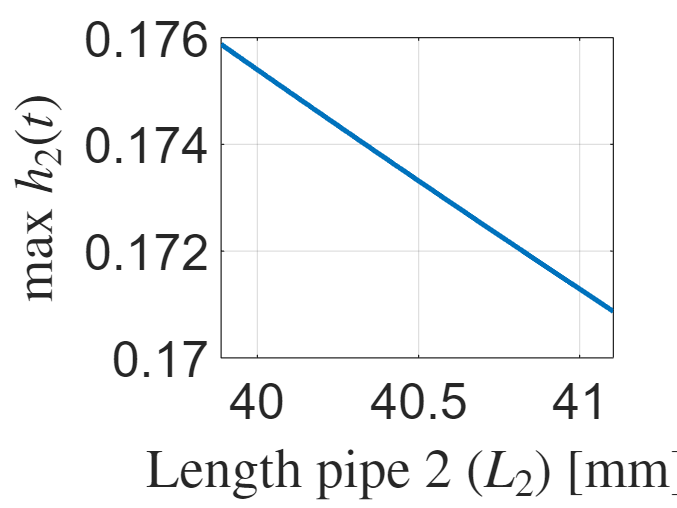


figure;
%% colecting the amplitude
plot(subs(L_1/sin((pi-varphi)/2),varphi,varphi_vec(idx))*1e3,peak_amp_pipe_2,'LineWidth',2);grid on;
xlabel('Length pipe 2 ($L_2$) [mm]','Interpreter','latex');
ylabel ('max $h_2(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Plotting $h_2(t)$

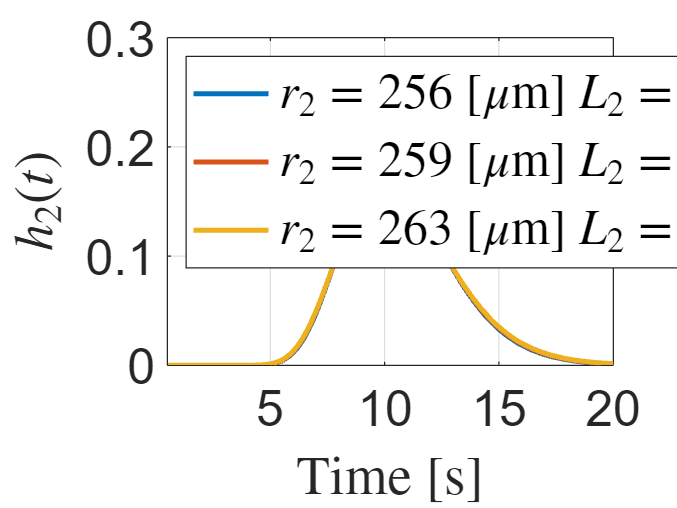

%Validation
%Evaluating the channel impulse response
%Matlab code to evaluate the integral
syms t x rd r rd v varphi D C_0
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(2*r)*int(integrand, rd, 0, 2*r));
%Performing the integral
c_avg=1/(2*r)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[2*r,1])-subs(c_avg,[rd,C_0],[0,1]);

samples=[1,round(length(idx)/2),length(idx)];
legend_text=cell(1,length(samples));
m=1;
figure;
peak_amp_pipe_2=zeros(1,length(idx));
for i=samples
    L_2=L_1/sin((pi-varphi)/2);

    %Evaluating the mean velocity [2, pag. 54]
    v_char=r^2*p0/(3*mu*L_2);

    %Evaluating the Effective Diffusion
    %[1, Eq.(4.54) pp.77]
    D_eff=r^2*v_char^2/48/D_coeff;

    c_avg_param_int=subs(c_avg_int,[x,D,v],[L_2,D_eff,v_char]);

    %evaluating the channel impulse response
    h_turn=diff(c_avg_param_int,t);
    r_2=r_vs_varphi_pipe_2(idx(i));
    L_2_val=double(subs(L_2,varphi,varphi_vec(idx(i))));
    fplot(subs(h_turn,[r,varphi],[r_2,varphi_vec(idx(i))]),[tau_1/10 4*tau_1],'LineWidth',2); grid on; hold on;
    
    %legend on the plot
    legend_text{m}=strcat('$r_2=',num2str(r_2*1e6,3),'$ [$\mu$m] $L_2=',num2str(L_2_val*1e3,3),'$ [mm]');
    m=m+1;
    
end

legend({legend_text{:}},...
    'Location','northwest','NumColumns',1,'Interpreter',"latex",'FontSize',fontsize);%

axis([tau_1/10 4*tau_1 0 0.3])

xlabel('Time [s]','Interpreter','latex');
ylabel ('$h_2(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Results Pipe 3

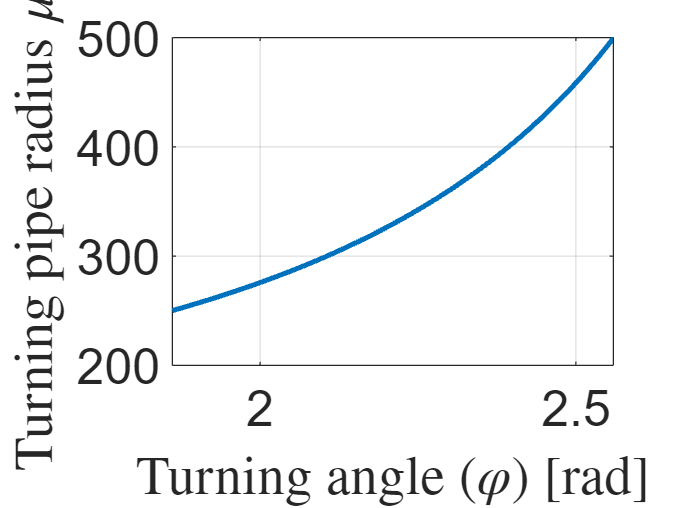

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'pipe_3_r_vs_varphi.mat'))

idx=find(r_vs_varphi_pipe_3~=0);

figure;
plot(varphi_vec(idx),r_vs_varphi_pipe_3(idx)*1e6,'LineWidth',2); grid on;
xlabel('Turning angle ($\varphi$) [rad]','Interpreter','latex');
ylabel ('Turning pipe radius $\mu$m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

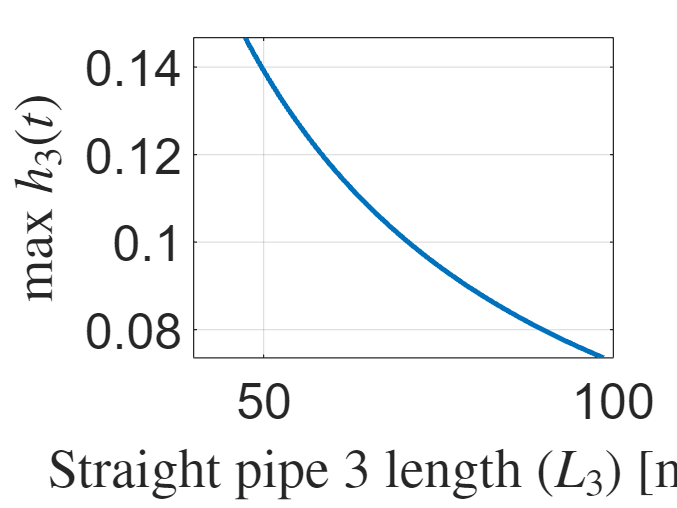


%Validation
%Evaluating the channel impulse response
%Matlab code to evaluate the integral
syms t x rd r rd v varphi D C_0
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(2*r)*int(integrand, rd, 0, 2*r));
%Performing the integral
c_avg=1/(2*r)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[2*r,1])-subs(c_avg,[rd,C_0],[0,1]);

% figure;
peak_amp_pipe_3=zeros(1,length(idx));
for i=1:length(idx)
    L_3=L_1/sin((pi-varphi)/2);

    %Evaluating the mean velocity [2, pag. 54]
    v_char=r^2*p0/(3*mu*L_3);

    %Evaluating the Effective Diffusion
    %[1, Eq.(4.54) pp.77]
    D_eff=r^2*v_char^2/48/D_coeff;

    c_avg_param_int=subs(c_avg_int,[x,D,v],[L_3,D_eff,v_char]);

    %evaluating the channel impulse response
    h_turn=diff(c_avg_param_int,t);
    % fplot(subs(h_turn,[r,varphi],[r_vs_varphi_pipe_2(idx(i)),varphi_vec(idx(i))]),[tau_1/10 3*tau_1]); grid on; hold on;

    peak_amp_pipe_3(i)=subs(h_turn,[t,r,varphi],[3*tau_1,r_vs_varphi_pipe_3(idx(i)),varphi_vec(idx(i))]);
end


figure;
%% colecting the amplitude
plot(subs(L_1/sin((pi-varphi)/2),varphi,varphi_vec(idx))*1e3,peak_amp_pipe_3,'LineWidth',2);grid on;
xlabel('Straight pipe 3 length ($L_3$) [mm]','Interpreter','latex');
ylabel ('max $h_3(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Plotting $h_3(t)$

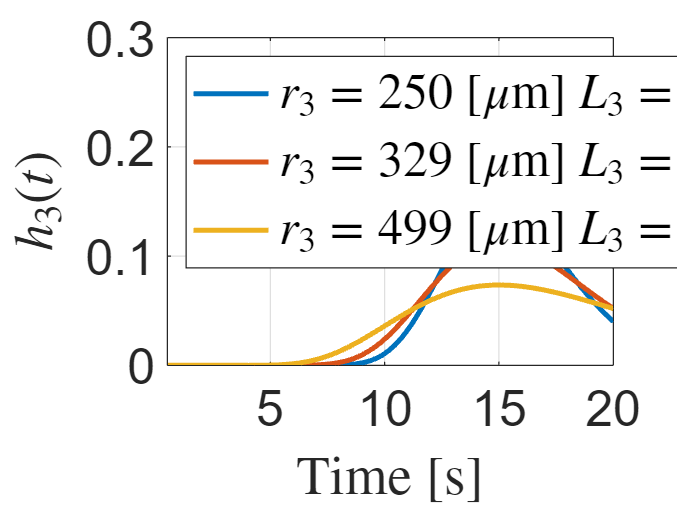

%Validation
%Evaluating the channel impulse response
%Matlab code to evaluate the integral
syms t x rd r rd v varphi D C_0
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(2*r)*int(integrand, rd, 0, 2*r));
%Performing the integral
c_avg=1/(2*r)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[2*r,1])-subs(c_avg,[rd,C_0],[0,1]);

samples=[1,round(length(idx)/2),length(idx)];
legend_text=cell(1,length(samples));
m=1;
figure;
peak_amp_pipe_2=zeros(1,length(idx));
for i=samples
    L_3=L_1/sin((pi-varphi)/2);

    %Evaluating the mean velocity [2, pag. 54]
    v_char=r^2*p0/(3*mu*L_3);

    %Evaluating the Effective Diffusion
    %[1, Eq.(4.54) pp.77]
    D_eff=r^2*v_char^2/48/D_coeff;

    c_avg_param_int=subs(c_avg_int,[x,D,v],[L_3,D_eff,v_char]);

    %evaluating the channel impulse response
    h_turn=diff(c_avg_param_int,t);
    r_3=r_vs_varphi_pipe_3(idx(i));
    L_3_val=double(subs(L_3,varphi,varphi_vec(idx(i))));
    fplot(subs(h_turn,[r,varphi],[r_3,varphi_vec(idx(i))]),[tau_1/10 4*tau_1],'LineWidth',2); grid on; hold on;
    
    %legend on the plot
    legend_text{m}=strcat('$r_3=',num2str(r_3*1e6,3),'$ [$\mu$m] $L_3=',num2str(L_3_val*1e3,3),'$ [mm]');
    m=m+1;
    
end

legend({legend_text{:}},...
    'Location','northwest','NumColumns',1,'Interpreter',"latex",'FontSize',fontsize);%

axis([tau_1/10 4*tau_1 0 0.3])

xlabel('Time [s]','Interpreter','latex');
ylabel ('$h_3(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] J. Crank. 1986. The Mathematics of Diffusion. Oxford University Press.

[4] A. B. Carlson, P. B. Crilly, and J. C. Rutledge, Communication Systems: An Introduction to Signals and Noise in Electrical Communication, 4th ed. New York City, NY: McGraw-Hill, 2002, p. 850.

[5] R. Chang, *Chemistry*. Boston, Mass.: McGraw-Hill Education, 1998.  